A=-7.35;
B=23.317;
C=0.8179;
D=0;
G=ss(A,B,C,D)

G =
 
  A = 
          x1
   x1  -7.35
 
  B = 
          u1
   x1  23.32
 
  C = 
           x1
   y1  0.8179
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



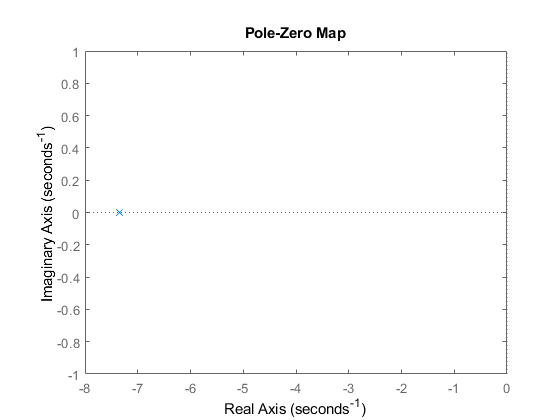

pzmap(G)

% 
T=0.001;
% e=0.458;
% wn=10;
 %Pb2=[1 2*e*wn wn^2];
Pb2=[1 8]

Pb2 =      1     8


Ps2=roots(Pb2)

Ps2 = -8

Pz2=exp(Ps2*T)

Pz2 = 0.9920

sysd=c2d(G,T,'zoh')

sysd =
 
  A = 
           x1
   x1  0.9927
 
  B = 
            u1
   x1  0.02323
 
  C = 
           x1
   y1  0.8179
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



Co=ctrb(sysd.A,sysd.B)

Co = 0.0232

rank(Co)

ans = 1

det(Co)

ans = 0.0232

V=obsv(sysd.A,sysd.C)

V = 0.8179

rank(V)

ans = 1


H=acker(sysd.A,sysd.B,Pz2)

H = 0.0278


%% integrador
Aa=[sysd.A(1,1) 0; -sysd.C(1,1) 1]

Aa =     0.9927         0
   -0.8179    1.0000


Ba=[sysd.B(1,1);0];

%2
Pba=conv(Pb2,[1 40]) %  añado el polo que me piden

Pba =      1    48   320


Ps=roots(Pba)

Ps =    -40
    -8


Pz=exp(Ps*T)

Pz =     0.9608
    0.9920



%3
Ha=acker(Aa,Ba,Pz)

Ha =     1.7156   -0.0164
